El VL53L0X es capaz de medir distancias de entre 50 y 2000 milímetros (medidas con un error asumible hasta 1200 mm max).

Representamos la recta ideal de medidas (si el sensor fuese perfecto) con respecto a la obtenida experimentalmente.Realizamos la calibración simultanea 

Realizaremos la calibración simultanea de los dos sensores. Para identificarlos, uno de ellos tiene atado un cable por lo que, hasta que los coloquemos en su posición definitiva, se llamarán** "cc" **(con cable) y **"sc"** (sin cable).

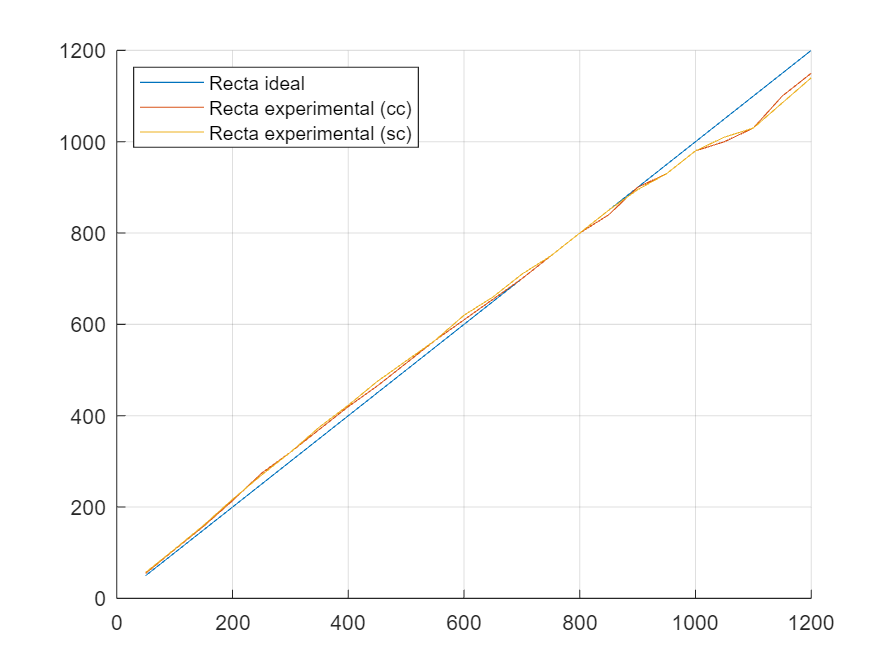

distancia_teorica=[50:50:1200];
distancia_medida_cc=[55 107 158 214 274 320 370 420 465 515 565 610 655 700 750 800 840 900 930 980 1000 1030 1100 1150];
distancia_medida_sc=[57 108 160 217 270 320 375 423 475 520 565 620 660 710 750 800 850 895 930 980 1010 1030 1085 1140];
figure()
grid on
hold on
plot(distancia_teorica,distancia_teorica)
plot(distancia_teorica,distancia_medida_cc)
plot(distancia_teorica,distancia_medida_sc)
legend("Recta ideal", "Recta experimental (cc)", "Recta experimental (sc)",'Location','northwest')
hold off

Ahora, realizamos una regresión lineal para obtener la ecuacion de ajuste de los datos experimentales de cada sensor.

% ajustamos a una parábola ya que es el polinomio que mejor se ajusta a simple vitsa
pol_cc = polyfit(distancia_teorica,distancia_medida_cc,2) 

pol_cc =    -0.0001    1.0895    1.3982


pol_sc = polyfit(distancia_teorica,distancia_medida_sc,2) 

pol_sc =    -0.0001    1.1217   -1.7490


Representamos las rectas de ajuste con la ideal

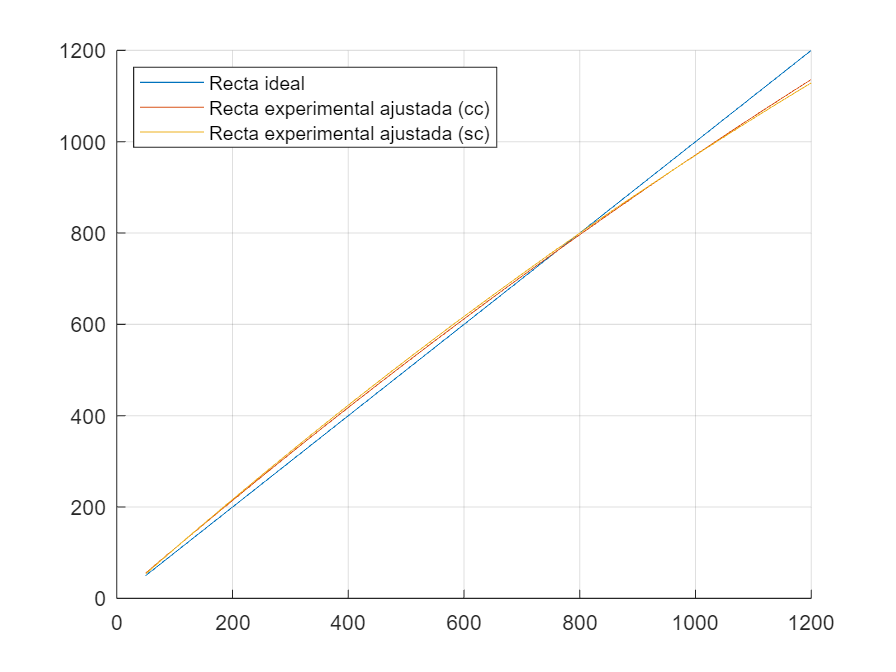

x = 50:1:1200;
y_teo = polyval([1 0],x);
y_exp_cc = polyval(pol_cc,x);
y_exp_sc = polyval(pol_sc,x);

figure()
grid on
hold on
plot(x,y_teo)
plot(x,y_exp_cc)
plot(x,y_exp_sc)
legend("Recta ideal","Recta experimental ajustada (cc)", "Recta experimental ajustada (sc)", 'Location','northwest')
hold off

Si quisieramos que la recta (ajustada) experimental coincidiese con la teórica, no sería posible realizar un control proporcional con una ganancia estática, dado que el valor de dicha ganancia debe de ir cambiando en función de la entrada. Por tanto, el control de los sensores lo realizaremos mediante una LookUpTable, la cual contendrá la ganancia necesaria para realizar dicho ajuste en función de la medida que arroje el sensor. Calculamos dicho vector de ganancia:

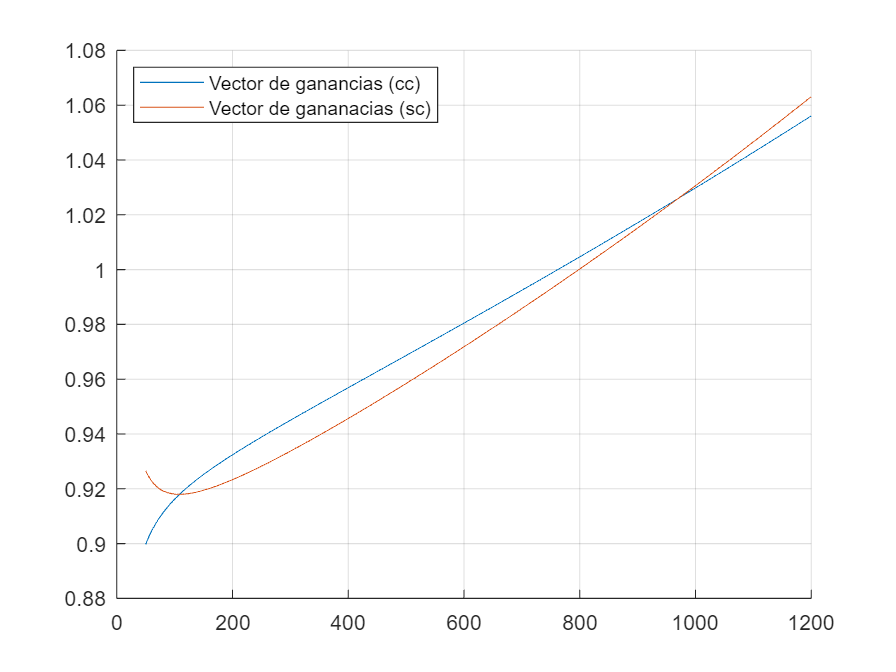

K_cc = zeros(1,1151);
K_sc = zeros(1,1151);

for i = 1:1:1151
    K_cc(i) = y_teo(i)/y_exp_cc(i);
    K_sc(i) = y_teo(i)/y_exp_sc(i);
end

figure()
grid on
hold on
plot(x,K_cc)
plot(x,K_sc)
legend("Vector de ganancias (cc)", "Vector de gananacias (sc)", 'Location','northwest')
hold off

Representando dichos vectores de ganancias, vemos como el valor de la ganancia varía desde un valor menor a la unidad hasta un valor superior a ella, pasando por la unidad en el punto de corte entre las rectas teórica y experimental. Para comprobar la efectividad de dicho ajuste, representaremos las medias experimentales al haberles aplicado la ganancia calculada.

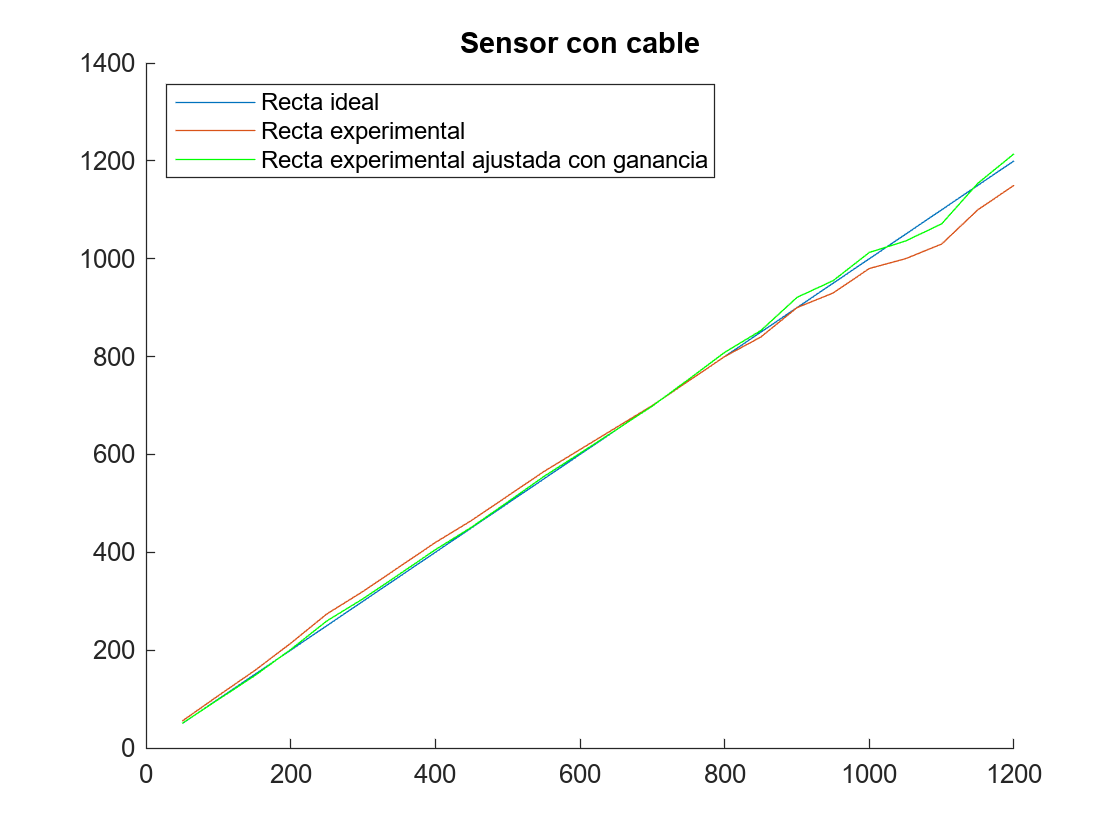

distancia_medida_ajustada_cc = zeros(1,24);
distancia_medida_ajustada_sc = zeros(1,24);
for i = 1:1:24
    distancia_medida_ajustada_cc(i)=distancia_medida_cc(i)*K_cc(distancia_medida_cc(i));
    distancia_medida_ajustada_sc(i)=distancia_medida_sc(i)*K_sc(distancia_medida_sc(i));
end

figure()
hold on
plot(distancia_teorica,distancia_teorica)
plot(distancia_teorica,distancia_medida_cc)
plot(distancia_teorica,distancia_medida_ajustada_cc, 'g')
title('Sensor con cable')
legend("Recta ideal","Recta experimental","Recta experimental ajustada con ganancia",'Location','northwest')
hold off

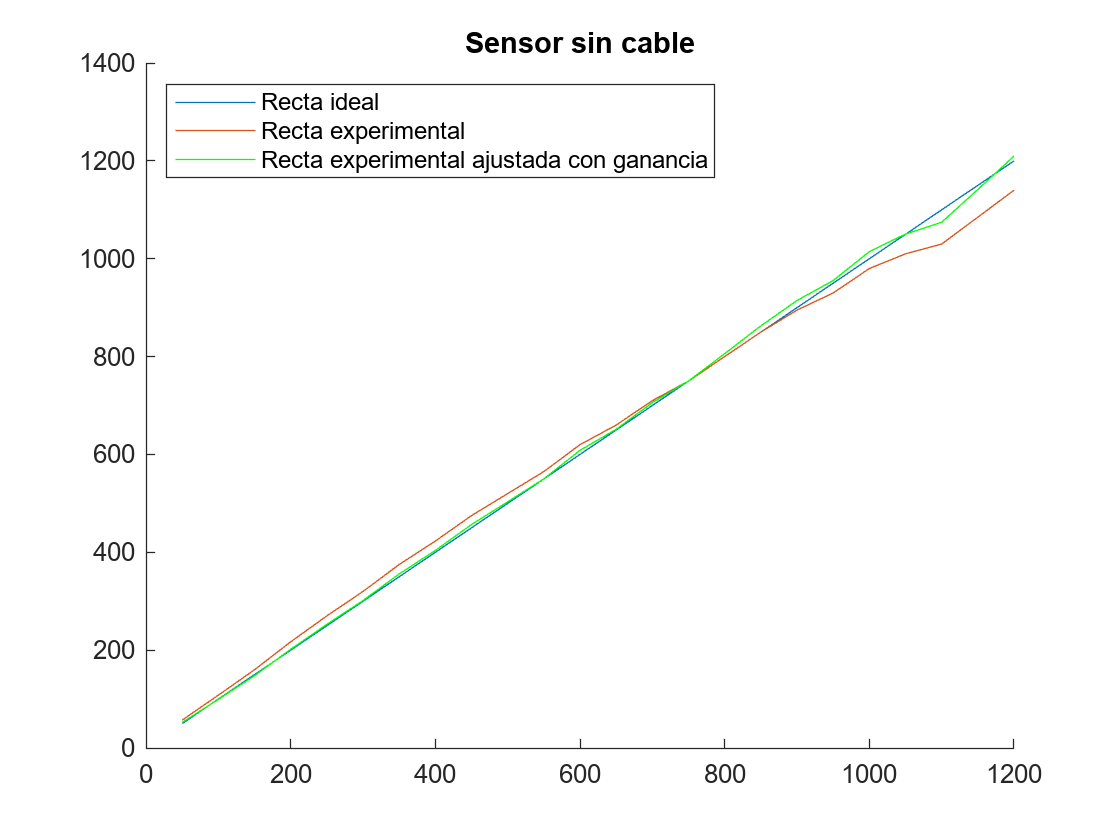

figure()
hold on
plot(distancia_teorica,distancia_teorica)
plot(distancia_teorica,distancia_medida_sc)
plot(distancia_teorica,distancia_medida_ajustada_sc,'g')
title('Sensor sin cable')
legend("Recta ideal","Recta experimental","Recta experimental ajustada con ganancia",'Location','northwest')
hold off

Comprobemos la mejora en el error después del ajuste:

error_sin_ajuste_cc = 0; error_sin_ajuste_sc = 0;
error_con_ajuste_cc = 0; error_con_ajuste_sc = 0;
for i = 1:1:24
    error_sin_ajuste_cc = error_sin_ajuste_cc+abs(distancia_teorica(i)-distancia_medida_cc(i))/(24*distancia_teorica(i));
    error_sin_ajuste_sc = error_sin_ajuste_sc+abs(distancia_teorica(i)-distancia_medida_sc(i))/(24*distancia_teorica(i));
    error_con_ajuste_cc = error_con_ajuste_cc+abs(distancia_teorica(i)-distancia_medida_ajustada_cc(i))/(24*distancia_teorica(i));
    error_con_ajuste_sc = error_con_ajuste_sc+abs(distancia_teorica(i)-distancia_medida_ajustada_sc(i))/(24*distancia_teorica(i));
end

mejora_cc = (error_sin_ajuste_cc-error_con_ajuste_cc)*100/error_sin_ajuste_cc

mejora_cc = 71.6842

mejora_sc = (error_sin_ajuste_sc-error_con_ajuste_sc)*100/error_sin_ajuste_sc

mejora_sc = 75.8809

Es decir, el ajuste de ganancia variable supone un 71,7 % de mejora en la resolución del sensor con cable y un 75,8 % en la resolución del sensor sin cable.

Finalmente, lo implementaremos en Simulink mediante una LookUpTable.